% Load and prepare data
X_data = importdata('x_data.txt')

X_data =      0     0     1     0     0     0     0     0     0     1     0     1     0     0     0     0     0     0     1     0     0     0     0     0     1     1     0     1     0     1     0     0     0     0     1     0     0     0     0     0     0     1     0     0     0     0     0     0     0     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0    


% add a column of ones for the bias
X_data = [ones(size(X_data,1),1), X_data];

y_labels = importdata('y_labels.txt');
% decided to stay with 1/0 labeling so following lines not used
% change 0's to -1
%y_labels(y_labels == 0) = -1

% Split Data between test and train
x_train = X_data(1:2000, :);
x_test = X_data(2001:end, :);

y_train = y_labels(1:2000, :);
y_test = y_labels(2001:end, :);

N = [200 500 800 1000 1500 2000];
accuracy = zeros(size(N));
idx = 1;
for n = N
    w = logistic_train(x_train(1:n,:), y_train(1:n), 1e-1, 20);
    h_x = 1./(1+ exp(-x_test*w));
    current_predictions = ones(size(x_test,1),1);
    current_predictions(h_x < 0.5) = 0;
    accuracy(idx) = 1 - sum(current_predictions ~= y_test)/size(x_test,1);
    idx = idx + 1;
end

number of iterations
     2

number of iterations
     2

number of iterations
     2

number of iterations
     2

number of iterations
     2

number of iterations
     2




%w = logistic_train(x_train, y_train, 1e-1, 10);
%h_x = 1./(1+ exp(-x_test*w));
%current_predictions = ones(size(x_test,1),1);
%current_predictions(h_x < 0.5) = 0;
%error = sum(current_predictions ~= y_test)/size(x_test,1);

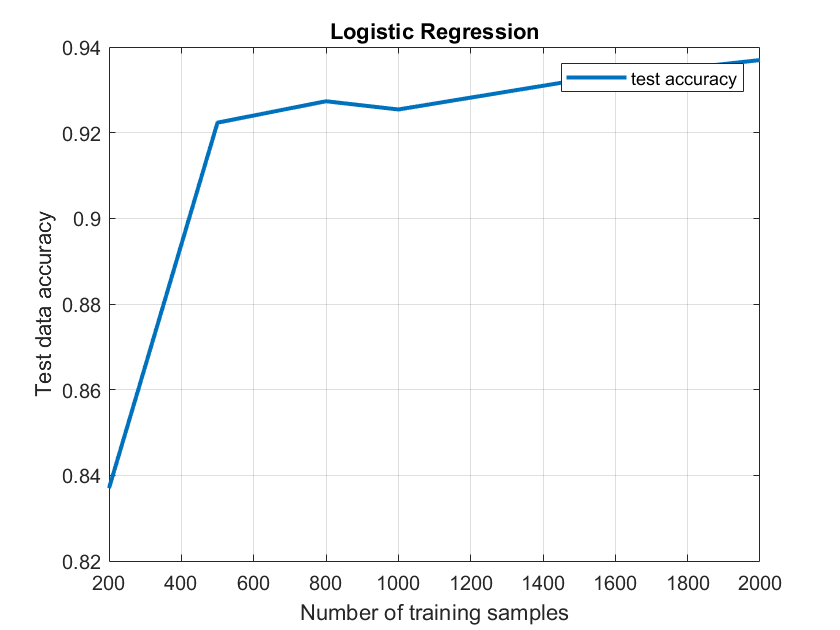

% plot and save the results
figure
plot(N, accuracy,'LineWidth',2)
grid on 
xlabel('Number of training samples') 
ylabel('Test data accuracy') 
title('Logistic Regression') 
legend('test accuracy')
savefig('p1_Logistic_regression_plot.fig')

function [weights] = logistic_train(data, labels, epsilon, maxiter)
% default arguments
if nargin<3
    epsilon = 1e-5;
    maxiter = 1000;
elseif nargin<4
    maxiter = 1000;
end

N = size(data,1);
weights = zeros(size(data,2),1);
lambda = 1;
j = 0;
change = 1;
last_predictions = ones(N,1);
% Switched to IRLS technique from textbook
while change > epsilon && j <= maxiter
    % sigmoid
    y = (1./(1+ exp(-data*weights)));
    % obtain the change in values for epsilon flag
    change = sum(abs(y - last_predictions))/N;
    last_predictions = y;
    E_w = data'*(y - labels);
    R = diag(y.*(1-y));
    H = data'*R*data;
    weights = weights - lambda*(H\E_w);
    % Things that I did not get working
    %    E_w = zeros(size(data,2),1);
    %for k = 1:size(weights,1)
     %   for i = 1:N
             %E_w(k) = E_w(k) + (h_x(i)-labels(i))*data(i,k);
             %E_w(k) = E_w(k) + log(1 + exp(-labels(i)*data(i,:)*weights)); %*data(i,k);
      %       E_w(k) = E_w(k) - h_x(i)*(1/(1 + exp(h_x(i)*data(i,:)*weights)))*data(i,k);
       % end 
    %end
    %E_w = E_w/N;
    %delta = -lambda*E_w;
    %disp('delta');
    %disp(delta);
    %weights = weights + delta;
    j = j + 1;
end
% checking to see how many iterations were actually performed
% disp('number of iterations');
% disp(j-1)

%
% code to train a logistic regression classifier
%
% INPUTS:
% data = n * (d+1) matrix withn samples and d features, where
% column d+1 is all ones (corresponding to the intercept term)
% labels = n * 1 vector of class labels (taking values 0 or 1)
% epsilon = optional argument specifying the convergence
% criterion - if the change in the absolute difference in
% predictions, from one iteration to the next, averaged across
% input features, is less than epsilon, then halt
% (if unspecified, use a default value of 1e-5)
% maxiter = optional argument that specifies the maximum number of
% iterations to execute (useful when debugging in case your
% code is not converging correctly!)
% (if unspecified can be set to 1000)
%
% OUTPUT:
% weights = (d+1) * 1 vector of weights where the weights correspond to
% the columns of "data"
%
end